# Laboratorio 3 Robótica: Modelo diferencial de primer orden

## Universidad Nacional de Colombia

## Alejandro Ojeda Olarte, Brayan Calderon, Mateo Rodriguez

## Asignacion de Ruta

Teniendo en cuenta el robot asignado y los resultados obtenidos en el Lab 1  Análisis de las características de un Robot Industrial y Modelo geométrico directo. Resuelva los siguientes enunciados.

#### 1.Se asigna un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentarla simulación de al menos una de las rutas propuestas, pueden crear y simular otras rutas y/o otros planos.

Para el grupo 1, nos toca el vector $\left\lbrack \begin{array}{ccc}
1 & 0 & 1
\end{array}\right\rbrack$. Se escoge la segunda figura de las opciones, y dado que el alcance del robot es 500mm, la dimensión L será 200mm. Se define una longitud del tramo largo recto de 150mm, un ancho de 150mm y un radio para el semicírculo de 50mm. La trayectoria se grafica a continuación.

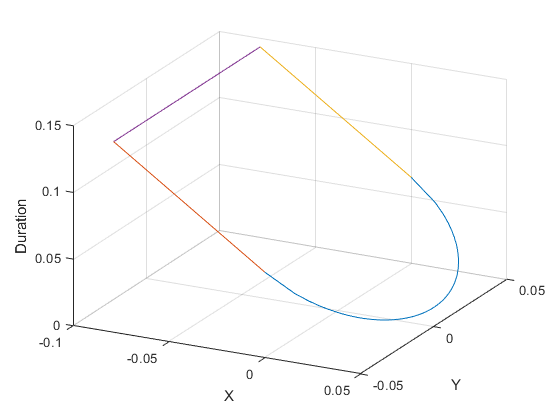

resolution=60;
radius=0.050; %In mm
L_side=0.150; %in mm

curve_y=linspace(-0.050,0.050,resolution);
curve_x=sqrt(-curve_y.^2 + radius^2);
curve_z=-curve_x+(L_side*cos(45)*0.5)+(radius*0.5);

side_x=linspace(-(L_side*cos(45)),0,resolution);
side_1y=ones(1,length(side_x))*-radius;
side_2y=ones(1,length(side_x))*+radius;
sides_z=-side_x+(L_side*cos(45)*0.5)+(radius*0.5);

cross_x=ones(1,length(side_x))*min(side_x);
cross_y=linspace(-radius,radius,resolution);
cross_z=ones(1,length(side_x))*max(sides_z);

clf
plot3(curve_x,curve_y,curve_z)
hold on
plot3(side_x,side_1y,sides_z)
plot3(side_x,side_2y,sides_z)
plot3(cross_x,cross_y,cross_z)
hold off
xlabel('X')
ylabel('Y')
zlabel('Duration')
grid on

view([27 28])

## Modelo diferencial de primer orden

Considerando que para que el robot ejecute los movimientos, se desea establecer una relación entre las velocidades del efector final y las articulaciones.

#### 1. Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numericos, NO simbólico) en función de los ángulos de articulación.

L(1) = Link([0 0.152 0 0],'modified');
L(2) = Link([0 0.120 0 pi/2 0 pi/2],'modified');
L(3) = Link([0 0 0.244 0],'modified');
L(4) = Link([0 -0.010 0.213 0 0 -pi/2],'modified');
L(5) = Link([0 0.083 0 -pi/2],'modified');
L(6) = Link([0 0.082 0 pi/2],'modified');
UR3 = SerialLink(L,'name','Universal Robot UR3')

 
UR3 = 
 
Universal Robot UR3 (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.152|          0|          0|          0|
|  2|         q2|       0.12|          0|      1.571|      1.571|
|  3|         q3|          0|      0.244|          0|          0|
|  4|         q4|      -0.01|      0.213|          0|     -1.571|
|  5|         q5|      0.083|          0|     -1.571|          0|
|  6|         q6|      0.082|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              

#### 2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para:

            
$$V_H =\left\lbrack \begin{array}{c}
100\\
200\\
50
\end{array}\right\rbrack \frac{\mathrm{mm}}{s}\;,\;\;\;\omega_H =\left\lbrack \begin{array}{c}
5\\
10\\
-5
\end{array}\right\rbrack \frac{\mathrm{rad}}{s}$$


## Integración

Ahora con la ayuda de los algoritmos desarrollados y de la GUI construida.

#### 1. Ubique la ruta seleccionada con la orientación indicada dentro del espacio diestro del robot.

clf

%Posicion del origen de la trayectoria
trajOrigin_x=0.2;
trajOrigin_y=0;
trajOrigin_z=0.3;

poses=UR3.ikunc(transl(curve_x(1)+trajOrigin_x,curve_y(1)+trajOrigin_y,curve_z(1)+trajOrigin_z)*troty(45+180,'deg')*trotz(90,'deg'))

poses =     0.2405    0.0668   -1.2284   -1.1800    1.7400    0.1717


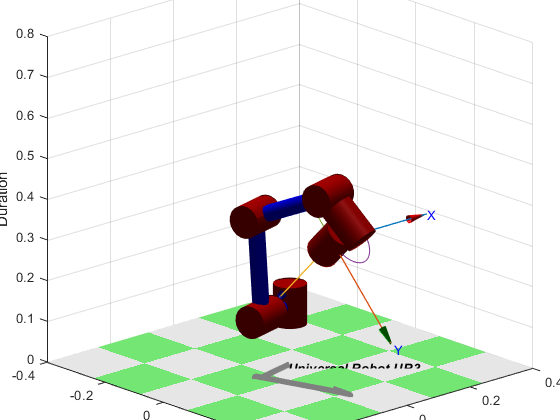

UR3.plot(poses,'workspace',[-0.4 0.4 -0.4 0.4 0 0.8])
hold on

plot3(curve_x+trajOrigin_x,curve_y+trajOrigin_y,curve_z+trajOrigin_z)
plot3(side_x+trajOrigin_x,side_1y+trajOrigin_y,sides_z+trajOrigin_z)
plot3(side_x+trajOrigin_x,side_2y+trajOrigin_y,sides_z+trajOrigin_z)
plot3(cross_x+trajOrigin_x,cross_y+trajOrigin_y,cross_z+trajOrigin_z)
xlabel('X')
ylabel('Y')
zlabel('Duration')
grid on

#### 2. Defina un conjunto de puntos equidistantes que pertenezcan a la ruta (viapoints). Mínimo 60 puntos. El eje z de la herramienta debe mantenerse perpendicular al plano que contiene la ruta.

#### 3. Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta.

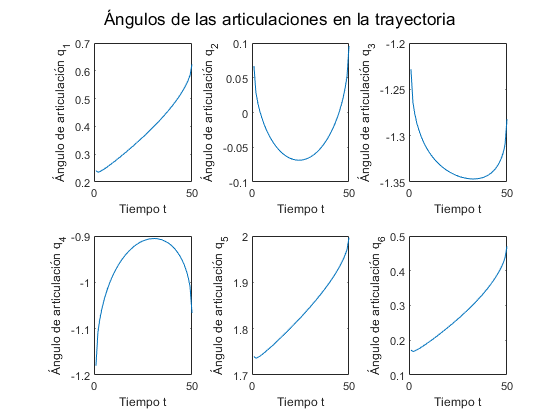

%Tramo recto 1
CurveLinePoints=zeros(6,resolution);
TestValues=[0,0,0,0,0,0];
for i=1:resolution
    TestValues=UR3.ikunc(transl(curve_x(i)+trajOrigin_x,curve_y(i)+trajOrigin_y,curve_z(i)+trajOrigin_z)*troty(45+180,'deg')*trotz(90,'deg'));
    CurveLinePoints(1,i)=TestValues(1);
    CurveLinePoints(2,i)=TestValues(2);
    CurveLinePoints(3,i)=TestValues(3);
    CurveLinePoints(4,i)=TestValues(4);
    CurveLinePoints(5,i)=TestValues(5);
    CurveLinePoints(6,i)=TestValues(6);
end
clf;

%TIEMPO DEFINIDO ARBITRARIAMENTE, HAY QUE CAMBIAR
t=linspace(1,resolution,resolution);

sgtitle('Ángulos de las articulaciones en la trayectoria')
subplot(2,3,1);
plot(t,CurveLinePoints(1,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_1') 
subplot(2,3,2);
plot(t,CurveLinePoints(2,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_2') 
subplot(2,3,3);
plot(t,CurveLinePoints(3,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_3') 
subplot(2,3,4)
plot(t,CurveLinePoints(4,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_4') 
subplot(2,3,5)
plot(t,CurveLinePoints(5,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_5') 
subplot(2,3,6)
plot(t,CurveLinePoints(6,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_6') 

#### 4. Calcule las velocidades en cada viapoint de manera que la herramienta recorra la ruta a una velocidad de 500 mm/s. Presente gráficas de velocidad de cada articulación.